# ** conv()**: **It expands a polynomial**

1.$G\left(s\right)=\frac{10}{\left(s+7\right)\left(s+2\right)}$

num1 = 10;
denum1 = conv([1 2],[2 3])

denum1 =      2     7     6


tf(num1, denum1)

ans =
 
        10
  ---------------
  2 s^2 + 7 s + 6
 
Continuous-time transfer function.



2.$G\left(s\right)=\frac{2s+3}{\left(s^2 +2s+5\right)\left(s+7\right)}$

num2 = [2 3]

num2 =      2     3


denum2 = conv([1 2 5], [1 7])

denum2 =      1     9    19    35


tf(num2, denum2)

ans =
 
          2 s + 3
  -----------------------
  s^3 + 9 s^2 + 19 s + 35
 
Continuous-time transfer function.



# **[Z P K]: converting zeros, poles and gain to their TF**

1.$\frac{X\left(s\right)}{U\left(s\right)}=\frac{10}{\left(s+7\right)\left(s+2\right)}$

%%       zero, [poles], gain)
sys1 = zpk([], [-7 -2], 10)

sys =
 
      10
  -----------
  (s+7) (s+2)
 
Continuous-time zero/pole/gain model.




%% The is no zero for the numnerator

2.$\frac{Y\left(s\right)}{U\left(s\right)}=\frac{16\left(s+3\right)}{\left(s+2\right)\left(s+8\right)}$

%%        zero,[poles],gain)
sys2 = zpk(-3,[-2 , -8], 16)

sys =
 
   16 (s+3)
  -----------
  (s+2) (s+8)
 
Continuous-time zero/pole/gain model.



### **tf2zp: Transfer Function to zeros and poles**

%% Finding the zeros, poles and gain
[z, p, ~] = tf2zp(16*[1 3], [1 10 16])

z = -3

p =     -8
    -2


% [z, p, k] = tf2zp(16*[1 3], [1 10 16])

# **DC Gain**

1.$G\left(s\right)=\frac{4}{s^2 +5\ldotp 5s+7\ldotp 5}$

num3 = 4;

num3 = 4

denum3 = conv([1 2.5], [1 3]);

denum3 =     1.0000    5.5000    7.5000


ans =
 
          4
  -----------------
  s^2 + 5.5 s + 7.5
 
Continuous-time transfer function.




% Finding DC gain
DCGAIN1 = dcgain(num, denum)

DCGAIN1 = 9.6000


% K is the gain
[z1, p1, K1] = tf2zp(num3, denum3)


z1 =

  0×1 empty double column vector



p1 =    -3.0000
   -2.5000


K1 = 4

2.$G\left(s\right)=\frac{10}{\left(s+5\right)}$

num4 = 10;

num4 = 10

denum4 = [1 5];

denum4 =      1     5



% Finding DC gain
DCGAIN2 = dcgain(num4, denum4)

DCGAIN2 = 2


% K is the gain
[z2, p2, K2] = tf2zp(num4, denum4)


z1 =

  0×1 empty double column vector



p1 = -5

K1 = 10

3.$G\left(s\right)=\frac{16\left(s+3\right)}{\left(s+2\right)\left(s+8\right)}$

num4 = conv(16, [1 3])

num4 =     16    48


denum4 = conv([1 2], [1 8])

denum4 =      1    10    16



% sys = tf(num4, denum4)

sys =
 
     16 s + 48
  ---------------
  s^2 + 10 s + 16
 
Continuous-time transfer function.



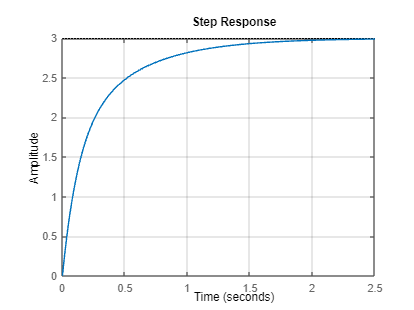


% applying a unit step
step(sys) 
grid on


% K is the gain
[z3, p3, K3] = tf2zp(num4, denum4)

z = -3

p =     -8
    -2


K = 16


% DC gain
DCGAIN3 = dcgain(num4, denum4)

k4 = 3

4.$G\left(s\right)=\frac{8}{\left(2s+5\right)\left(s+3\right)}$

num5 = 8;
denum5 = conv([2 5], [1 3]);

% Finding DC gain
DCGAIN4 = dcgain(num5, denum5)

DCGAIN4 = 0.5333


% K is the gain
[z4, p4, K4] = tf2zp(num5, denum5)


z4 =

  0×1 empty double column vector



p4 =    -3.0000
   -2.5000


K4 = 4

# **Minreal**

**FUNCTION TO FIND POLE-ZERO CANCELLATION**

**Minimal Transfer Function**

*****Minimum Order Transfer Function"

**The function used is called "*****minreal(sys)"***


$$G\left(s\right)=\frac{16\left(s+3\right)}{\left(s+2\right)\left(s+8\right)}$$


num = conv(16, [1 3])

num =     16    48


denom = conv ([1 3], [1 8])

denom =      1    11    24



sys = tf(num,denom)

sys =
 
     16 s + 48
  ---------------
  s^2 + 11 s + 24
 
Continuous-time transfer function.



minreal(sys)

ans =
 
   16
  -----
  s + 8
 
Continuous-time transfer function.

